disp("hello world")

hello world


G1 = tf([2], [1 3])

G1 =
 
    2
  -----
  s + 3
 
Continuous-time transfer function.
Model Properties


s = tf('s');
G2 = 5/(s+8)
step(G1,4);
hold on; %sostiene graficas anterior 
step(G2, 4)



## Espacio de estados


Gss = ss(G1) %de Tf a SS

Gss =
 
  A = 
       x1
   x1  -3
 
  B = 
       u1
   x1   2
 
  C = 
       x1
   y1   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties


Gtf = tf(Gss) %de SS a Tf

Gtf =
 
    2
  -----
  s + 3
 
Continuous-time transfer function.
Model Properties



A = [5 3 1; 0 4 1; 1 0 -3];
B = [4 2; 6 5; 0 0];  %numero de columnas de B son las entradas
C = [1 2 3];
D = [4 6];
Gss = ss(A,B,C,D)

Gss =
 
  A = 
       x1  x2  x3
   x1   5   3   1
   x2   0   4   1
   x3   1   0  -3
 
  B = 
       u1  u2
   x1   4   2
   x2   6   5
   x3   0   0
 
  C = 
       x1  x2  x3
   y1   1   2   3
 
  D = 
       u1  u2
   y1   4   6
 
Continuous-time state-space model.


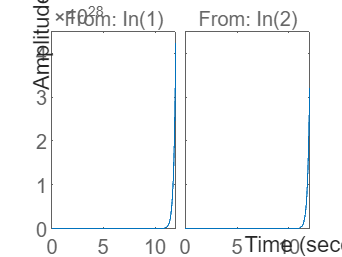

step(Gss)

eig(Gss) % polos, CRITERIO DE ESTABILIDAD

ans =    -3.0713
    5.3790
    3.6923


## ode45: simulacion no lineal

x0 = [1 3]'

x0 =      1
     3


A = [0 1; -4 -5];
B = [0 3]';
c = [0;0];

[T, X] = ode45(@(t,x)masa_resorte_friccion(t,x,control(x),A,B,c),[0 5], x0);
% ode45 simula masa resorte friccion en un tiempo de [0 5], a una 
% condicion inicial de x0

plot(T,X(:,1))
legend('x1 posicion')

figure()
plot(T,X(:,2))
legend('x2 velocidad')

## fmincon: Optimizacion

z0 = [2,3]

z0 =      2     3


z = fmincon(@(z)Fcosto(z),z0,[],[],[],[],[],[],@(z)restr(z))


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


z =     1.7500    1.2500


function J = Fcosto(z)
    J = z(1)^2+2*z(1)+z(2)^2+3*z(2);
end
function [c_desi, c_igual] = restr(z)
    c_igual = [z(1) + z(2) - 3];
    c_desi = [z(1) - 3
              z(2) - 4];
end

function dx = masa_resorte_friccion(t,x,u,A,B,c)
    % dx = A*x + B*u + c;
    dx = [x(2); 
        -(4+x(1)^2 + cos(t))*x(1)+u];
end

function u = control(x)
    kp = 100;
    kd = 20;
    x1d = 3;
    u = -kp*(x(1)-x1d) - kd*x(2);

end

